# 2-QAM

## Generate Data for Transmission

rng(1) % Seed the random number generator
N=1000-100; % Length of the data
dat=sign(randn(N,1)+1i*sign(randn(N,1))); % Generate random data
txname='tx_x14_fake.dat'; % name of the tx data file

% start transmission with 100 -1s
negative = -1*ones(100,1)-1i*ones(100,1);
dat= [negative.' dat.'].'

dat =   -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i



% Upsample the data
pulse_width = 100;
x_us=upsample(dat,pulse_width);

% Convolve the signal with a pulse
pulse=ones(pulse_width,1);
x=conv(x_us,pulse);

% Write TX data to a file
write_usrp_data_file(x,txname)

## Read in Transmitted Data

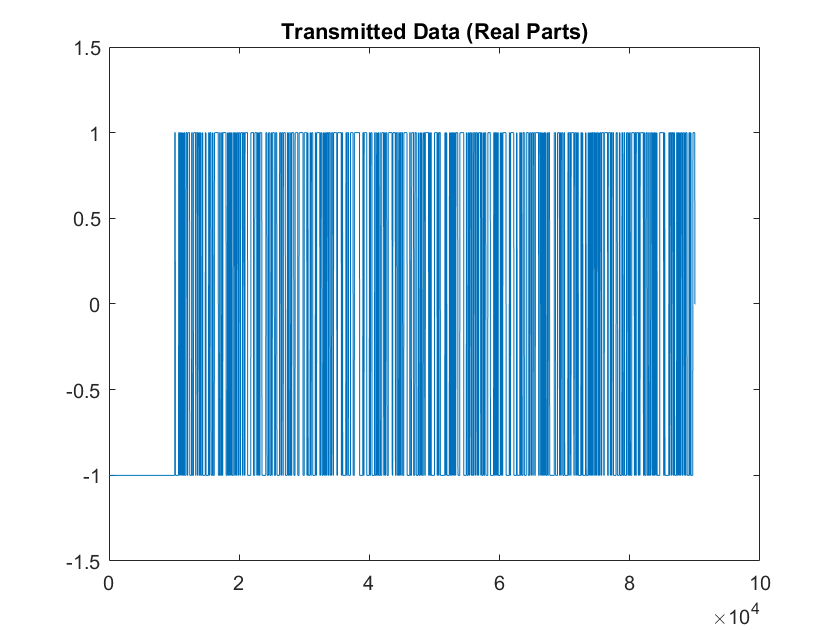

% Read in the Transmitted Data
txname='tx_x14.dat';
dat=read_usrp_data_file(txname);

% Plot the real part of the tx data
figure
plot(real(dat))
title('Transmitted Data (Real Parts)')
ylim([-1.5,1.5]);

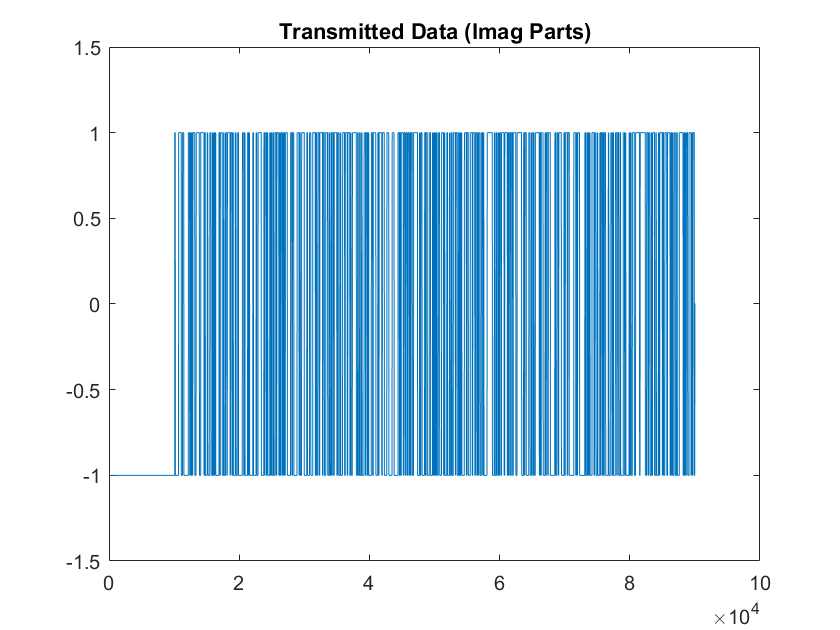


% Plot the imaginary part of the tx data
figure
plot(imag(dat))
title('Transmitted Data (Imag Parts)')
ylim([-1.5,1.5]);

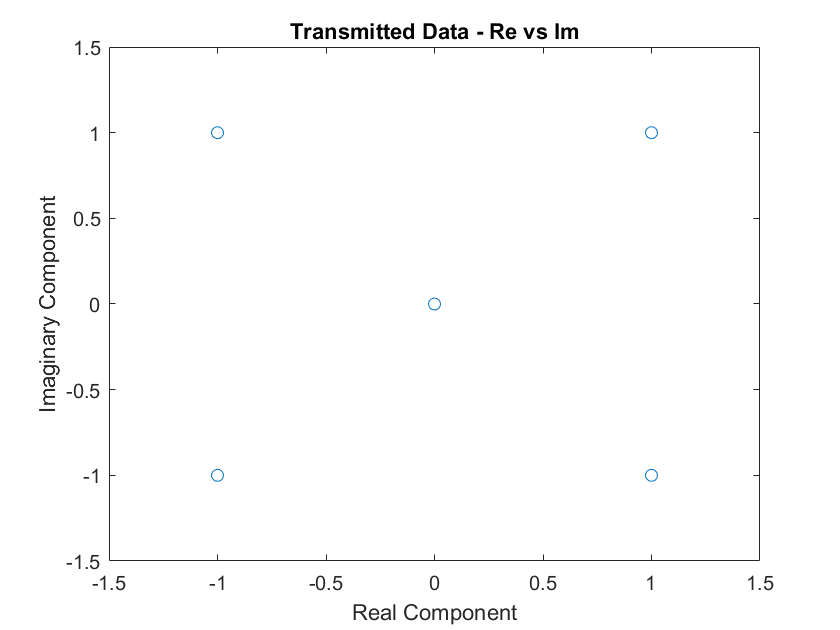


% Plot the real part vs the imaginary part of the tx
figure
plot(real(dat),imag(dat), 'o')
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('Transmitted Data - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Read in the Received Data

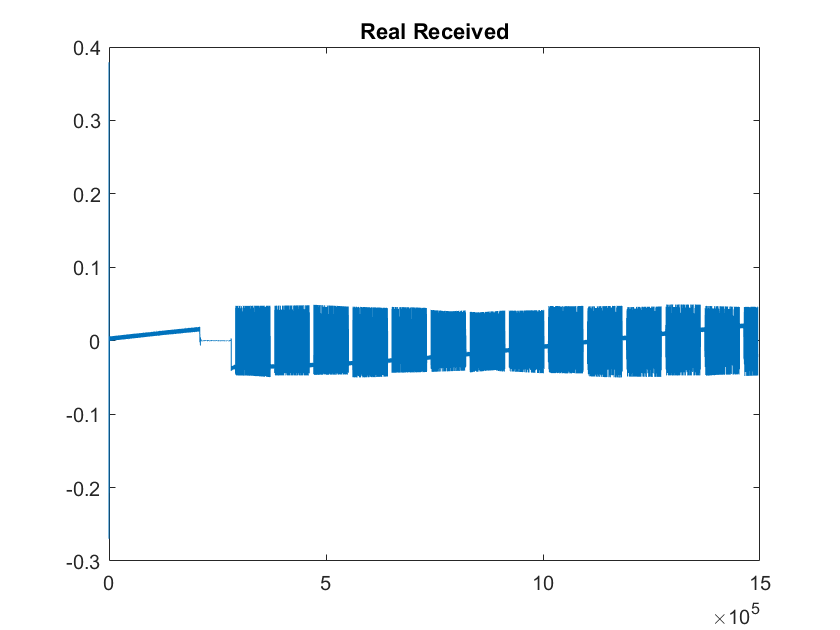

% Read in the received data
rxname='rx_x14.dat';
read=read_usrp_data_file(rxname);

% Plot the real part of rx
figure
plot(real(read))
%ylim([-1.5,1.5]);
title('Real Received')

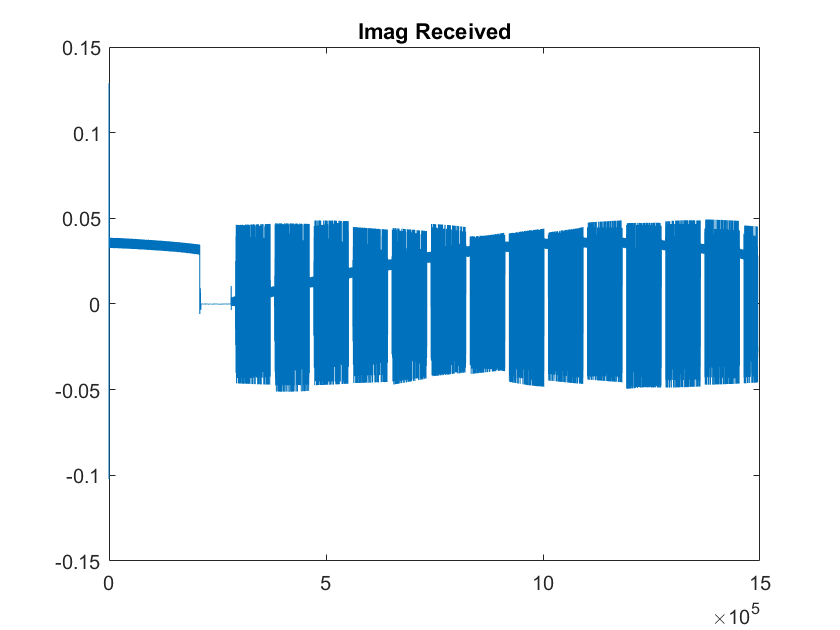


% Plot the imaginary part of rx
figure
plot(imag(read))
title('Imag Received')

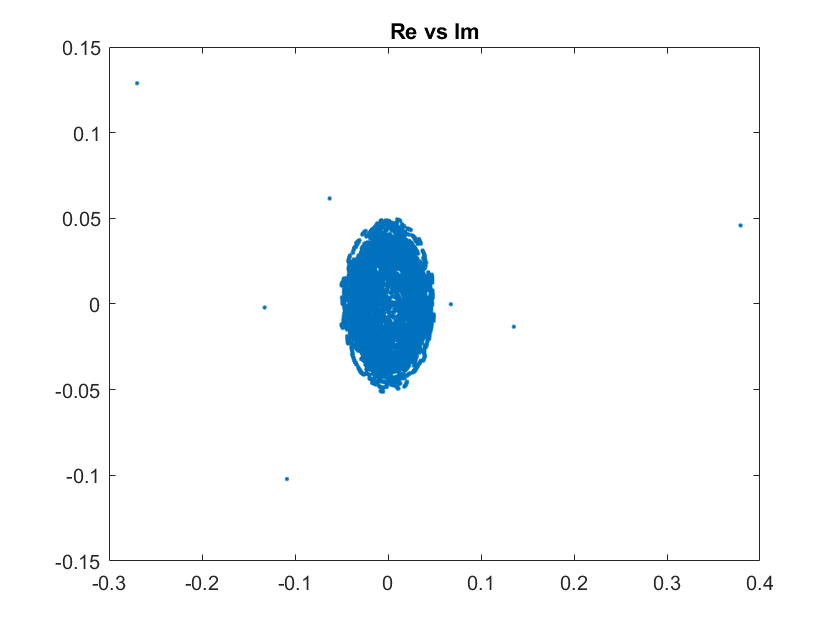

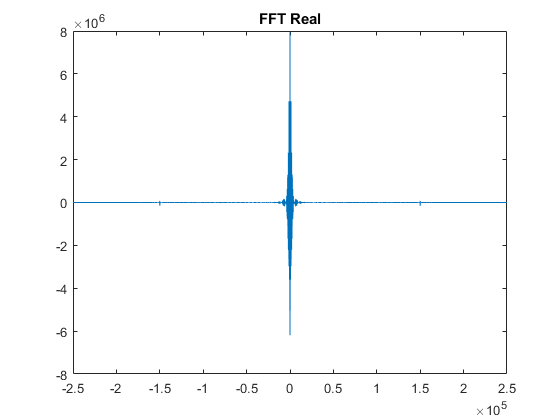

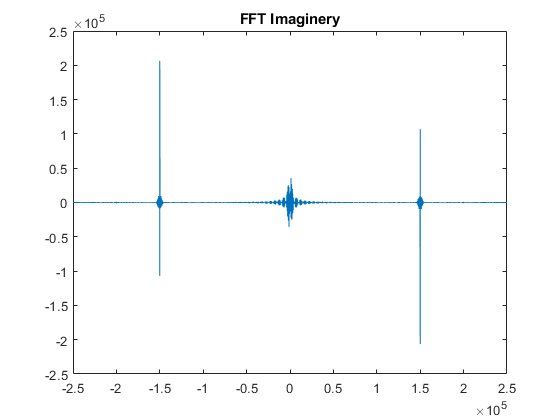

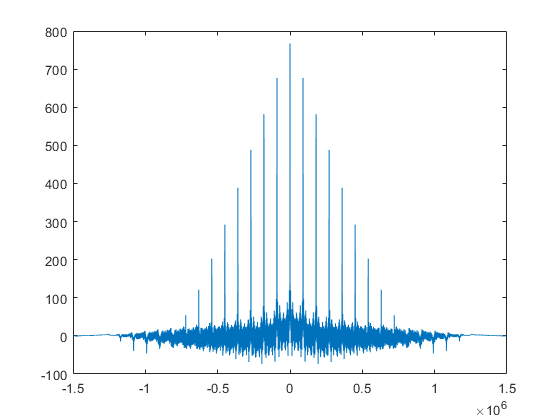


% Plot real vs imaginary components of the rx signal
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

## Cross-correlation of RX and TX

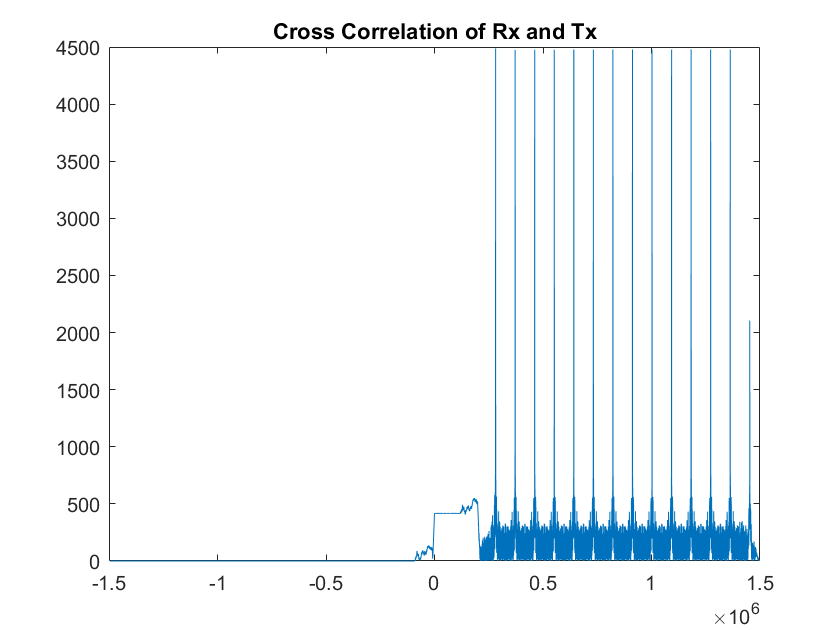

%Find cross-correlation of received and transmitted signals
[r, lags]=xcorr(read,dat);

% Plot Cross-correlation
plot(lags,abs(r))
title('Cross Correlation of Rx and Tx')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% Find the lag where the cross-correlation of rx/tx is greatest
% This indicates where the signal begins
startPos = lags(find(abs(r) == max(abs(r))))

startPos = 281591

## Unknown Purpose

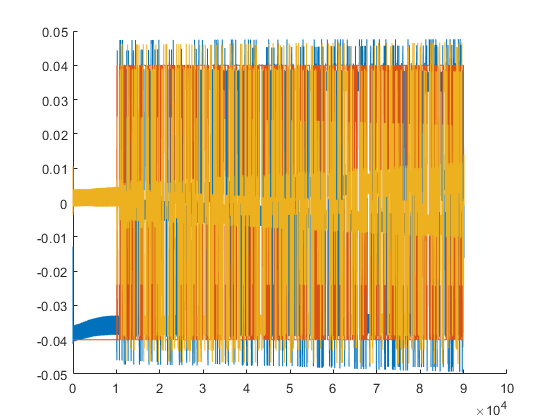

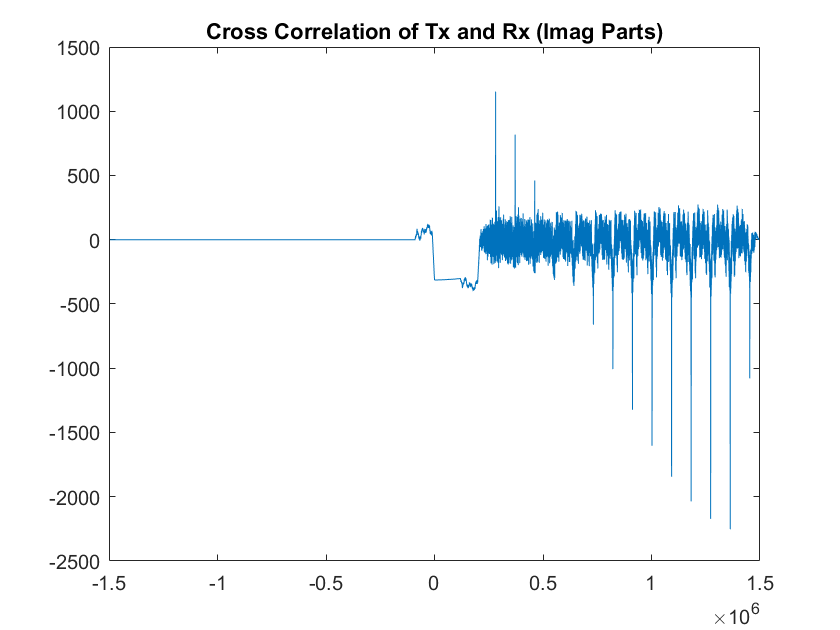

figure
hold on
plot(real(read(startPos:startPos+length(dat))))
plot(real(dat)*.04)
plot(imag(read(startPos:startPos+length(dat))))

## Adjust for phase shift

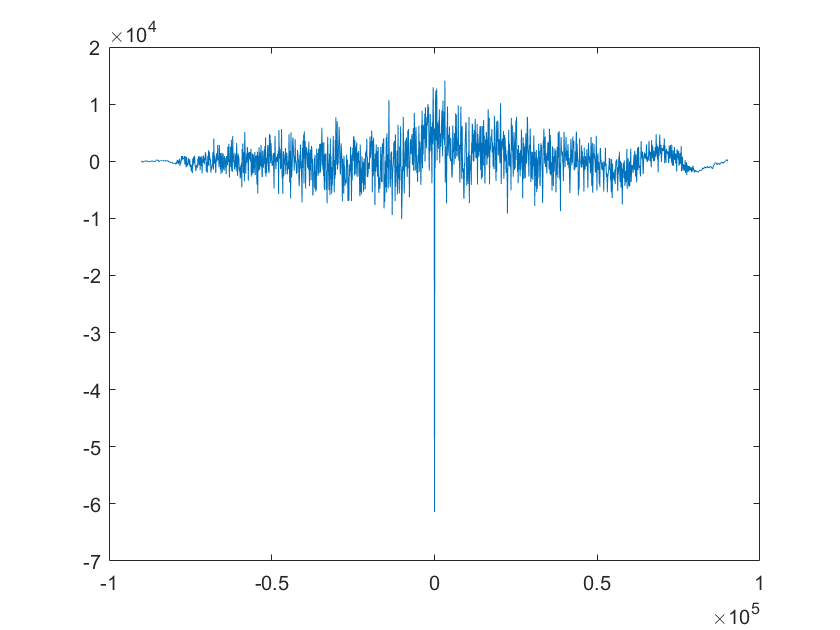

% Isolate the portion of the received signal corresponding to the data we
% sent
read_shifted=read(startPos:end);
signal_rx = read_shifted(1:length(dat));

% Cross-correlate real part of received signal and transmitted signal
% Tells us if our start position for the signal is correct
rx_mag_1 = sign(real(signal_rx)) + sign(imag(signal_rx));
[r, lags]=xcorr(real(rx_mag_1),real(dat));
plot(lags,r)


% If our signal always begins with -1s, we can fix the sign of our received
% data by multiplying by the negative of the sign of the first bit of the
% received data
signal_rx_sign = signal_rx; %-1*sign(signal_rx(1))*signal_rx;

% Solve for phi
% y[k]=x[k]e^j*(f_delta*k+phi)+n[k]
% x[k]=e^j(pi/4 + m*pi/2)
% y[k]^4 = e^(j*pi) * e^(4*f_delta*k+4*theta)
y_norm=signal_rx_sign./rms(abs(signal_rx_sign));
y_norm_4=y_norm.^4;

% Find the maximum values of the real and imaginary components of the fft
% of y[k]^4
fft_y = fft(y_norm_4);
real_max = max(real(fft_y));
im_max = max(imag(fft_y));

% 4*phi + pi = atan(im_max / real_max)
phi = (atan(im_max/real_max) - pi)/4

phi = -0.7717

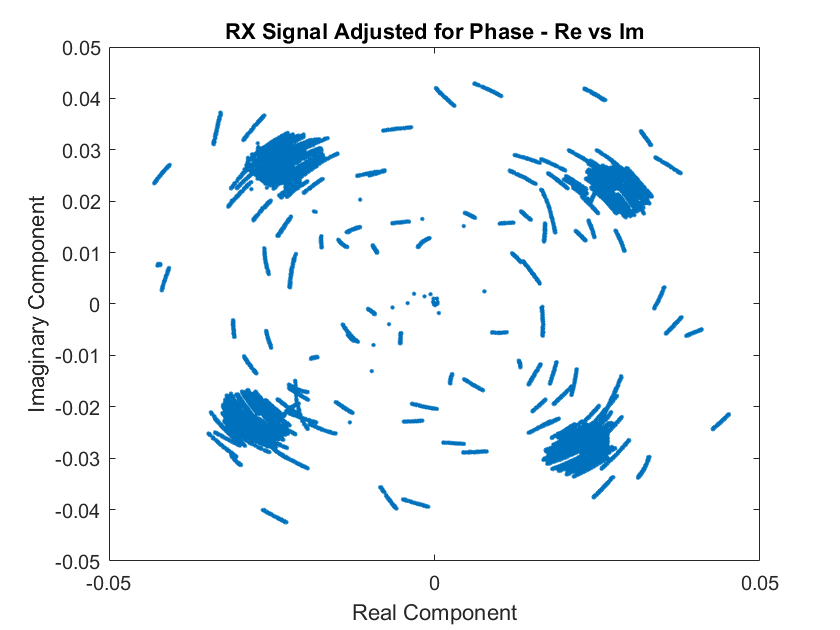


% Find complex exponential to adjust for phase offset
f_delta = 0;
Fs = 500000; % sampling frequency
k=1:length(signal_rx_sign);
offset=exp(j*(f_delta*(k-1)*1/Fs+phi));

% Multiply rx signal by the complex exponential to adjust for phase offset
read_offset=times(signal_rx_sign,offset.');

% Plot real vs imaginary of adjusted rx signal
figure
plot(real(read_offset),imag(read_offset),'.')
title('RX Signal Adjusted for Phase - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Error Calculation

% Downsample TX signal to get original signal
data_ds = downsample(dat,pulse_width);

% Downsample RX signal
rx_ds = downsample(read_offset,pulse_width,pulse_width/2);

% Find number of errors in real and imaginary components, downsampling the
% rx signal
error_real=sign(-downsample(real(read_offset),pulse_width,pulse_width/2))-sign(real(data_ds));
error_imag=sign(-downsample(imag(read_offset),pulse_width,pulse_width/2))-sign(imag(data_ds));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));

% Sum errors and calculate error rate
err_total = err_real + err_imag;
err_rate=err_total/(length(rx_ds)*2);
err_rate

err_rate = 0.5006

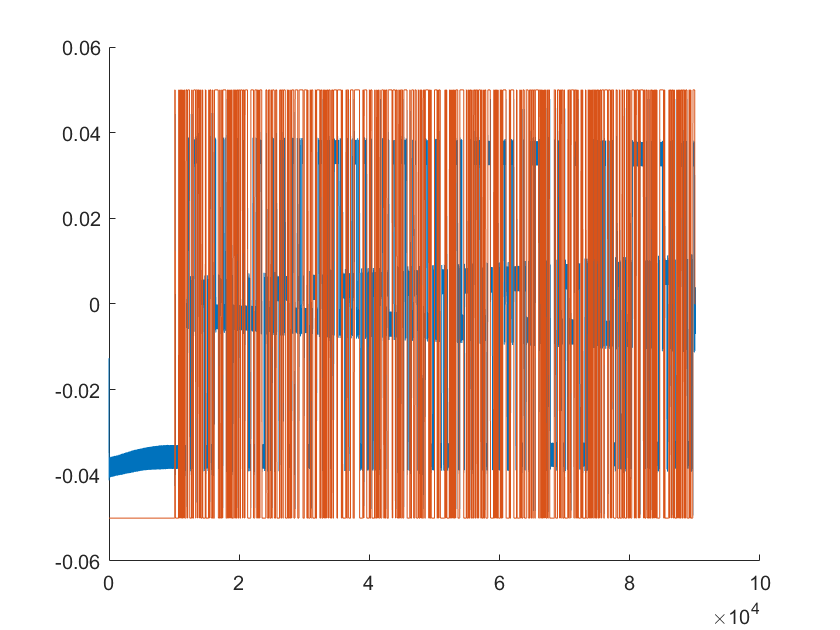

figure
hold on
plot(real(read_offset))
plot(real(dat)*.05)
ylim([-.06,.06])

## Extra


% Downsample the received signal, with a phase offset of half the pulse
% width
signal_rx = downsample(signal_rx_sign, pulse_width, pulse_width/2);

% Calculate error rate 
rx_real = sign(real(signal_rx));
rx_im = sign(imag(signal_rx));
signed_down_real = sign(real(data_ds));
signed_down_im = sign(imag(data_ds));
error_real=rx_real-signed_down_real;
error_imag=rx_im-signed_down_im;
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));
err_total = err_real + err_imag;
err_rate=err_total/(length(signal_rx)*2);
%error = sign(signal_rx)-sign(data_ds);
%error=sign(real(signal_rx_noise))-real(real(dat));
%error = error_real + error_imag;
%err_num=length(find(error~=0));
%err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 0.5006

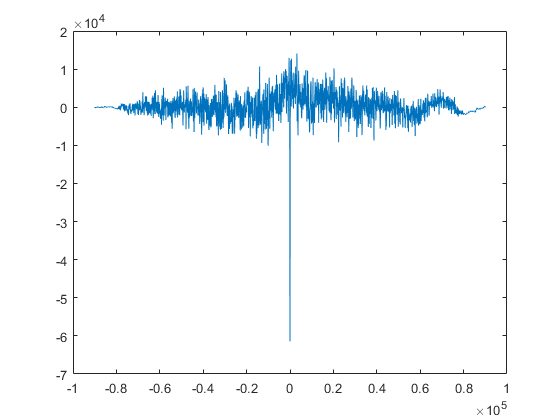

[r, lags]=xcorr(real(rx_tot),real(dat));
plot(lags,r)

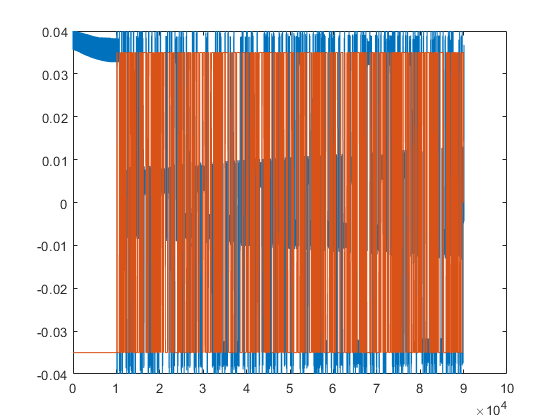

figure
plot(real(signal_rx_up))
ylim([-0.04,0.04])
%xlim([0,2e5])
hold on;
plot(real(dat)*0.035)
hold off;

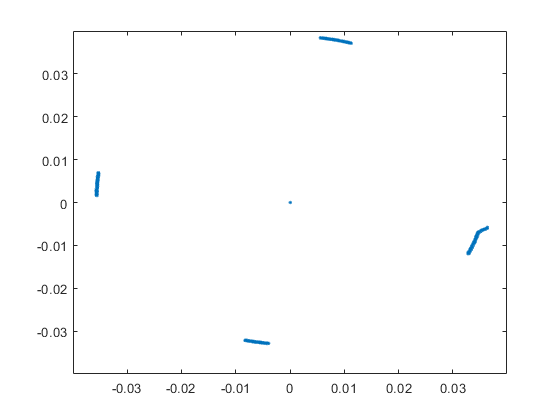

plot(real(signal_rx),imag(signal_rx),'.')

%xlim([-0.04,0.04])

## Attempt to adjust for phase shifting

y_norm=signal_rx_up./rms(abs(signal_rx_up));
y_norm_4=y_norm.^4;

fft_y = fft(y_norm_4)

fft_y = 	1.0e+04 *

   6.3548 - 5.8085i
   0.6796 - 0.6447i
   0.3692 - 0.3998i
   0.2354 - 0.3119i
   0.1613 - 0.2567i
   0.1198 - 0.2008i
   0.0902 - 0.1722i
   0.0719 - 0.1386i
   0.0684 - 0.1296i
   0.0570 - 0.1162i


xval = max(real(fft_y))

xval = 6.3548e+04

yval = max(imag(fft_y))

yval = 6.2109e+03


phi = (atan(yval/xval) - pi)/4

phi = -0.7610

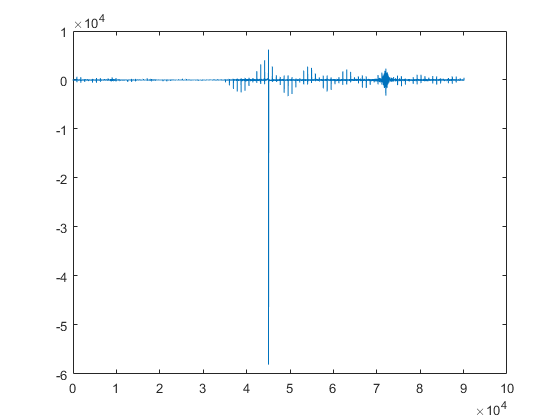

phi = 1.4519e+04


plot(imag(fftshift(fft(y_norm_4))));




% 2f = 200000
% 2phi = arctan(-1422497.7246/-642656);
ff_real = real(fft(y_norm_4));
max_val = max(ff_real)

max_val = 6.3548e+04




% 
% %check = real(y_norm_2(82330))
% ff_im = imag(fft(y_norm_2));
% 
% phi=atan(ff_im(max_val)/ff_real(max_val))/2
% f=0/2;

k=1:length(signal_rx_up);
offset=exp(j*(0*(k-1)*1/500000+phi));
%read_ds=read(153580:153580+length(dat)-1);
% read_ds=downsample(read_ds,20);
read_offset=times(signal_rx_up,offset');

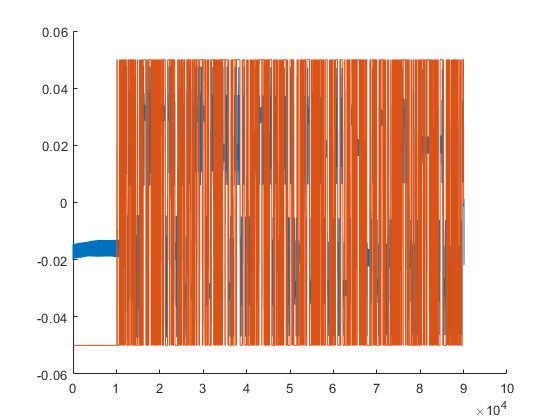

figure

hold on
plot(real(read_offset))
plot(real(dat)*.05)
ylim([-.0,.06])

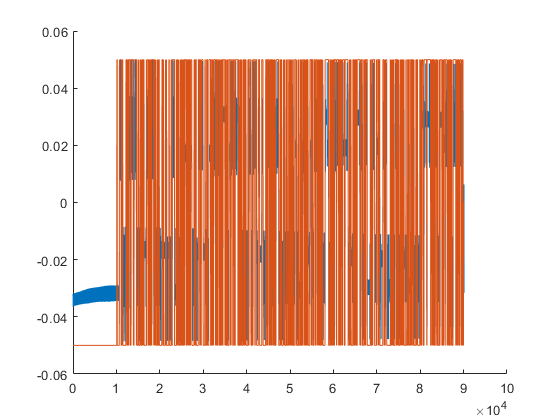

figure
hold on
plot(-imag(read_offset))
plot(imag(dat)*.05)
ylim([-.06,.06])

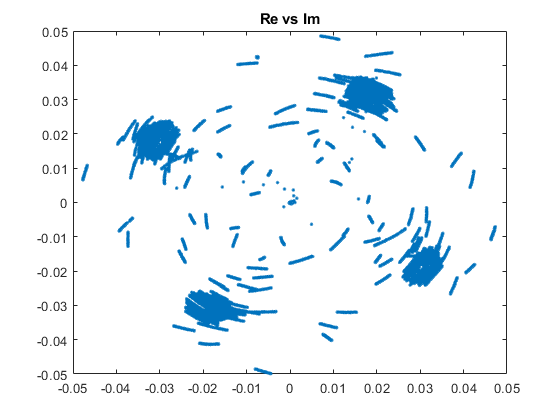


% Plot real vs imaginary
figure
plot(real(read_offset),imag(read_offset),'.')
title('Re vs Im')

error_real=sign(-downsample(real(read_offset),100,50))-sign(real(data_ds));
error_imag=sign(-downsample(imag(read_offset),100,50))-sign(imag(data_ds));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));
err_total = err_real + err_imag;
err_rate=err_total/(length(signal_rx)*2);
%error = sign(signal_rx)-sign(data_ds);
%error=sign(real(signal_rx_noise))-real(real(dat));
%error = error_real + error_imag;
%err_num=length(find(error~=0));
%err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 0.0011